% Laplace01.m

close all
clc
clear

global w


% System: INPUTS  ========================================================
  N = 5001;
  tMax = 2*pi;
  
  w =2;

  m = 1;
  
  b =0.6;
  
  k =2;
  
  % Initial conditions: displacment / velocity
  u0 = [0, 0];
 
 % Input amplitude
   A = 1; 
  
% Setup  ================================================================

  tS = linspace(0,10*pi,N);
  
  % Input function
    yS = A.*cos(w*tS);
  
  % ODE coefficients
    K(1) = -b/m;
    K(2) = -k/m;

    K(3) =  -(b*w/m)*A;
  

% Solve ODE  ============================================================
  tSpan = linspace(0,10*pi, N); 
  RelTol = 1e-6;
  options = odeset('RelTol',RelTol);

  [t, SOL] = ode45(@(t,u) FNode(t,u,K), tSpan, u0, options);

  x = SOL(:,1);


 wN = sqrt(k/m)

wN = 1.4142

 wR = sqrt(wN^2 - b^2/(2*m^2))

wR = 1.3491

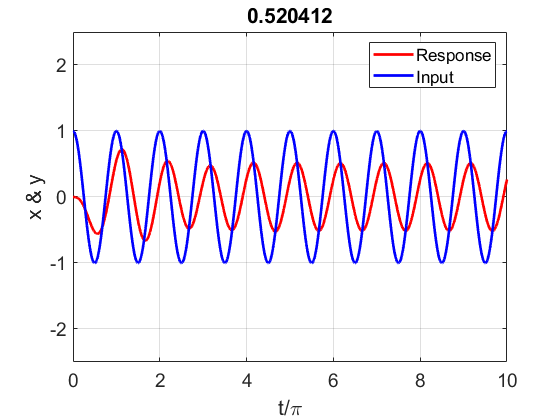

  
% GRAPHICS ===============================================================

figure(1)
%    set(gcf,'units','normalized');
%    set(gcf,'position',[0.05 0.05 0.45 0.45]);
%    set(gcf,'color','w');
   FS = 14; LW = 2;
   
   box on

   plot(t./pi,x,'r','linewidth',LW);

   hold on
   plot(tS./pi,yS,'b','linewidth',LW)

   ylim([-2.5 2.5])
   grid on
   
   xlabel('t/\pi')
   ylabel('x & y')
   legend('Response','Input')
   set(gca,'fontsize',FS)
   
   title(max(x(t>3*pi)))

   


% FUNCTIONS  =============================================================   
   

function du = FNode(t,u,K)

global w

z = u(1);

zDot = u(2);

du = zeros(2,1);

% First derivative dz/dt

du(1) = zDot;

% ODE: Second derivative d2y/dt2

%du(2) = K(1)*zDot + K(2)*z + K(3)*cos(w*t) + K(4)*sin(w*t);
 du(2) = K(1)*zDot + K(2)*z + K(3)*sin(w*t) ;
%du(2) = K(1)*zDot + K(2)*z + K(3)*cos(w*t) ;
%du(2) = K(1)*zDot + K(2)*z + 0.1*cos(w*t) ;
end